% Define filter specifications
fs_audio = 3300; % Original audio file sampling frequency
low_freq = 300; % Lower cutoff frequency in Hertz
high_freq = 3000; % Upper cutoff frequency in Hertz
order = 10 % Filter order

order = 10

rp = 3; % Passband ripple in dB

% Adjust fs based on cutoff frequencies
fs = 2 * max(high_freq, fs_audio);

% Display filter design parameters
kp = low_freq / (fs / 2);
ks = high_freq / (fs / 2);
omega_p = 2 * atan(kp);
omega_s = 2 * atan(ks);

fprintf('Filter Design Parameters (Chebyshev Type I):\n');

Filter Design Parameters (Chebyshev Type I):


fprintf('Passband edge frequency (kp): %.4f\n', kp);

Passband edge frequency (kp): 0.0909


fprintf('Stopband edge frequency (ks): %.4f\n', ks);

Stopband edge frequency (ks): 0.9091


fprintf('Passband edge frequency (omega_p): %.4f rad\n', omega_p);

Passband edge frequency (omega_p): 0.1813 rad


fprintf('Stopband edge frequency (omega_s): %.4f rad\n', omega_s);

Stopband edge frequency (omega_s): 1.4756 rad



% Design the Chebyshev Type I bandpass filter
[b_cheby, a_cheby] = cheby1(order, rp, [low_freq, high_freq]/(fs/2), 'bandpass');

% Calculate passband ripple and stopband ripple
passband_ripple = rp; % Passband ripple is specified by the user
stopband_ripple = -20 * log10(eps(norm(b_cheby, 2))); % Stopband ripple in dB

fprintf('Passband Ripple: %.4f dB\n', passband_ripple);

Passband Ripple: 3.0000 dB


fprintf('Stopband Ripple: %.4f dB\n', stopband_ripple);

Stopband Ripple: 288.9888 dB


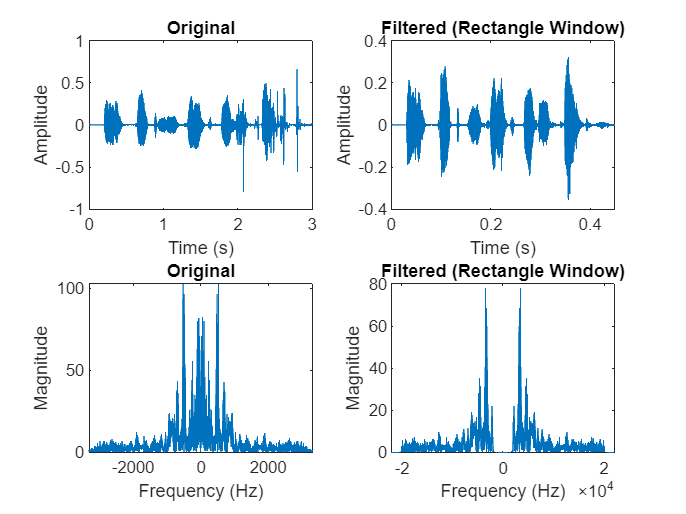


% Load the audio file
file_path = 'Goutami.wav';
[y, fs_audio] = audioread(file_path);

% If the audio file has a different sampling rate, resample it
if fs_audio ~= fs
    y = resample(y, fs, fs_audio);
end

% Apply the Chebyshev Type I bandpass filter to the audio signal
filtered_audio_cheby = filter(b_cheby, a_cheby, y);
Sampling_frequency=44100;
% Display and play the original signal in time and frequency domains
subplot(2,2,1);
t = (0:length(y)-1) / fs;
plot(t, y);
title('Original');
xlabel('Time (s)');
ylabel('Amplitude');
t = (0:length(filtered_audio_cheby)-1) / Sampling_frequency; % Time vector

subplot(2,2,2);
plot(t, filtered_audio_cheby);
title('Filtered (Rectangle Window)');
xlabel('Time (s)');
ylabel('Amplitude');

n = length(y);  % Set n based on the length of the signal
x = fft(y, n);
m = abs(x);
f = (0:length(x)-1) * fs / length(x);
X = fftshift(m);
fshift = (-n/2:n/2-1) * (fs/n);

% Filtered
nf = length(y);  % Set n based on the length of the signal
yf = fft(filtered_audio_cheby, nf);
mf = abs(yf);
ff = (0:length(yf)-1) * Sampling_frequency / length(yf);
Yf = fftshift(mf);
fshiftf = (-nf/2:nf/2-1) * (Sampling_frequency/nf);

subplot(2,2,3);
plot(fshift, X);
title('Original');
xlabel('Frequency (Hz)');
ylabel('Magnitude');

subplot(2,2,4);
plot(fshiftf, Yf);
title('Filtered (Rectangle Window)');
xlabel('Frequency (Hz)');
ylabel('Magnitude');

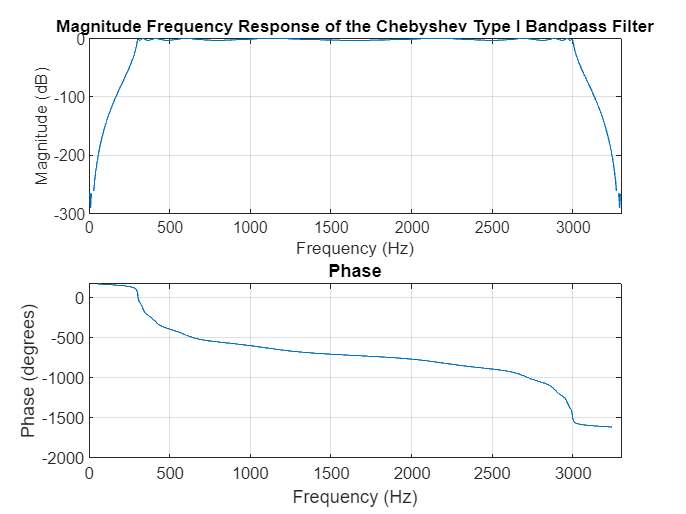



% Plot the frequency response of the Chebyshev filter
figure;
freqz(b_cheby, a_cheby, 1024, fs);
title('Magnitude Frequency Response of the Chebyshev Type I Bandpass Filter');